## Taller 11 Ecuaciones diferenciales:

#### modelo de ecuaciones presa depredador.

**Por:** Daniel Palacio González        **ID: **1000247116

**        Introducción:**

Dentro de los múltiples modelos de análisis y casos de estudio que se pueden plantear a través de las ecuaciones diferenciales, existe el modelo SIRV (modelo de presa-depredador). Este modelo de ecuaciones diferenciales sirve para el estudio de fenomenos como epidemias, pandemias y trasmisibilidad de enfermedades.

En este taller se realizará el análisis de este modelo aplicado en el planteamiento de una población dividida en varios grupos de suceptibles a contagio, infectados, recuperados y vacunados. Se espera que en esta práctica se logre identificar como las diferentes condiciones iniciales así como variables estado-dependientes afectan los resultados del análisis.

        **Solución a ecuación diferencial:**

Para este ejercicio se propone el siguiente sistema de ecuaciones diferenciales:

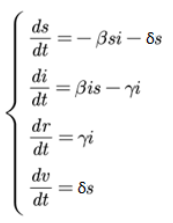

De donde se sabe que:

- s(t): Individuos suceptibles a infectarse.

- i(t): números de personas infectadas.

- r(t): cantidad de personas recuperadas.

- v(t): número de individuos vacunados.

Asimismo, se tienen las condiciones estado-dependientes:

- Tasa de transmisión: $\beta =0\ldotp 1$

- Tasa de recuperación: $\gamma =0\ldotp 02$

- Tasa de vacunación: $\delta =0\ldotp 001$

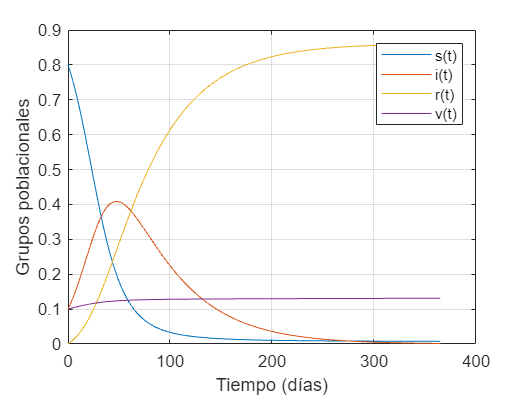

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación

syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci=[0.8 0.1 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[tiempo,salida]=ode45(fn,tspan,ci);

figure
plot(tiempo,salida)
grid on
hold on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
legend("s(t)","i(t)","r(t)","v(t)")

Como se puede observar en la gráfica de resultados a lo largo del tiempo varían las proporciones de los grupos de personas en el total de la población, iniciando por un pico de personas susceptibles, seguido por el pico de contagio y finalizando con un pico de las personas recuperadas.

**        Punto 1:**

Para este análisis se variará 5 veces la proporción de personas vacunadas en el tiempo cero con un cambio aumentativo de 0.02 iniciando en el valor de 0.5.

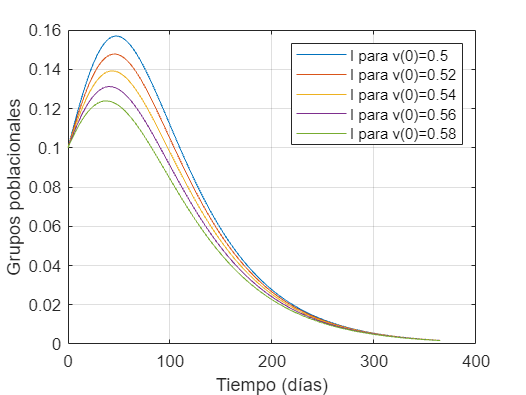

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación

syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci1=[0.4 0.1 0 0.5]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci2=[0.38 0.1 0 0.52]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci3=[0.36 0.1 0 0.54]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci4=[0.34 0.1 0 0.56]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci5=[0.32 0.1 0 0.58]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[t1,s1]=ode45(fn,tspan,ci1);
[t2,s2]=ode45(fn,tspan,ci2);
[t3,s3]=ode45(fn,tspan,ci3);
[t4,s4]=ode45(fn,tspan,ci4);
[t5,s5]=ode45(fn,tspan,ci5);

figure
plot(t1,s1(:,2),t2,s2(:,2),t3,s3(:,2),t4,s4(:,2), t5,s5(:,2))
grid on
hold on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
legend("I para v(0)=0.5","I para v(0)=0.52","I para v(0)=0.54","I para v(0)=0.56","I para v(0)=0.58")

Como se observa en la gráfica, a mayor tasa de personas vacunadas al inicio del estudio, menor es la altura del pico de personas contagiadas. Además, con el fin de que la tasa de contagios solo aumente hasta un 15% de población contagiada (0.15), se requiere que al menos un 54% (0.54) de la población se encuentre vacunada desde un inicio. 

**        Punto 2:**

En este punto se realizará un análisis de cómo influye en los resultados el aumento del porcentaje de poblacion infectada en el inicio del análisis.

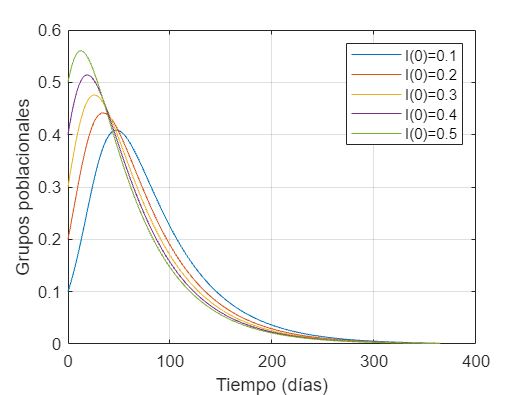

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación

syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci1=[0.8 0.1 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci2=[0.7 0.2 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci3=[0.6 0.3 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci4=[0.5 0.4 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]
ci5=[0.4 0.5 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[t1,s1]=ode45(fn,tspan,ci1);
[t2,s2]=ode45(fn,tspan,ci2);
[t3,s3]=ode45(fn,tspan,ci3);
[t4,s4]=ode45(fn,tspan,ci4);
[t5,s5]=ode45(fn,tspan,ci5);

figure
plot(t1,s1(:,2),t2,s2(:,2),t3,s3(:,2),t4,s4(:,2), t5,s5(:,2))
grid on
hold on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
legend("I(0)=0.1","I(0)=0.2","I(0)=0.3","I(0)=0.4","I(0)=0.5")

Como se evidencia, el aumento en la tasa de personas infectadas al inicio del estudio hace que el pico de los infectados se alcance más rápido, sin embargo, también hace que la diferencia entre el punto inicial de infectados y su mayor valor a lo largo del tiempo sea menor.

        **Punto 3:**

En este punto se realizará el análisis del modelo con 5 valores de beta, con valor inicial 0.1, reduciendo este con un salto de 0.02. Lo anterior con el fin de hallar cuál es el valor máximo de tasa de trasmisibilidad antes de que se genere una endemia.

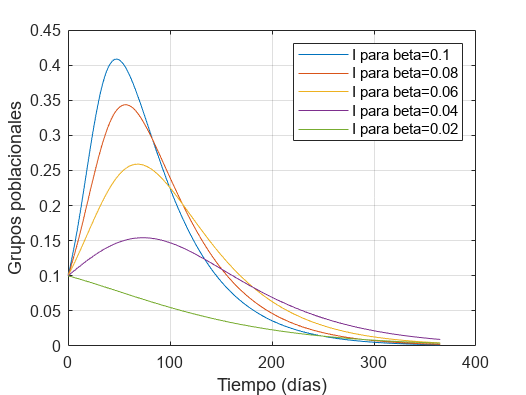

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación
contador=1; %contador para ciclo de solución
syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci=[0.8 0.1 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[tiempo,salida]=ode45(fn,tspan,ci);

figure
plot(tiempo,salida(:,2))
grid on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
hold on
beta=beta-0.02; %Disminución de beta

while contador<5 %Ciclo while para crear gráfica
    contador=contador+1; %Aumento de contador
    
%Planteamiento de ecuaciones con nuevo beta
    FS=-beta*s*i-delta*s; %EC susceptibles a infección
    FI=beta*s*i-gamma*i; %EC infectados
    FR=gamma*i; %EC recuperados
    FV=delta*s; %EC vacunados
    fn=odeFunction([FS FI FR FV],[s i r v]);

    [tiempo,salida]=ode45(fn,tspan,ci);

    plot(tiempo,salida(:,2))
    grid on
    xlabel("Tiempo (días)")
    ylabel("Grupos poblacionales")
    hold on
    beta=beta-0.02; %Disminución de beta
end
legend("I para beta=0.1","I para beta=0.08","I para beta=0.06","I para beta=0.04","I para beta=0.02")

Como se puede observar en la gráfica, cuando la tasa de transmisibilidad (beta) toma un valor de 0.02 la tasa de infectados a lo largo del tiempo no aumenta y, por tanto, no se considera que la enfermedad provoca una endemia.

**        Punto 4:**

En este caso se realizará el análisis con 5 valores diferentes para la tasa de recuperación (gamma), partiendo desde gamma=0.02 y con un salto creciente de 0.015. ¿Cuál es el valor mínimo de gamma para el cuál se evita una endemia?

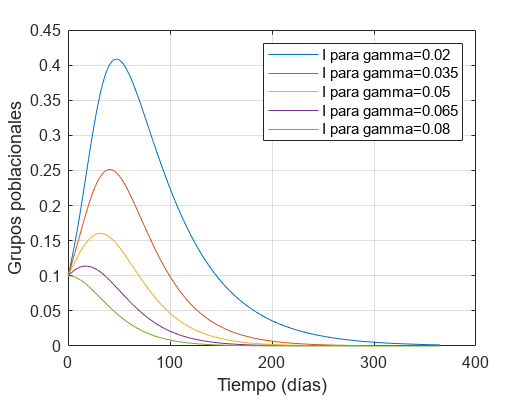

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación
contador=1; %contador para ciclo de solución
syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci=[0.8 0.1 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[tiempo,salida]=ode45(fn,tspan,ci);

figure
plot(tiempo,salida(:,2))
grid on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
hold on
gamma=gamma+0.015;

while contador<5 %Ciclo while para crear gráfica
    contador=contador+1; %Aumento de contador
    
%Planteamiento de ecuaciones con nuevo gamma
    FS=-beta*s*i-delta*s; %EC susceptibles a infección
    FI=beta*s*i-gamma*i; %EC infectados
    FR=gamma*i; %EC recuperados
    FV=delta*s; %EC vacunados
    fn=odeFunction([FS FI FR FV],[s i r v]);

    [tiempo,salida]=ode45(fn,tspan,ci);

    plot(tiempo,salida(:,2))
    grid on
    xlabel("Tiempo (días)")
    ylabel("Grupos poblacionales")
    hold on
    gamma=gamma+0.015; %Aumento de gamma
end
legend("I para gamma=0.02","I para gamma=0.035","I para gamma=0.05","I para gamma=0.065","I para gamma=0.08")

Tras realizar los análisis, se observa en la gráfica que, para un valor de tasa de recuperación (gamma) de 0.08 no se presentaría una endemia. Esto se evidencia en la gráfica pues el mayor valor de infectados se presenta en el tiempo=0 y, a medida que este avanza la tasa de infectados decrece.

**        Punto 5:**

Finalmente, se realizará el análisis del sistema aumentando el valor de la tasa de vacunación (delta) con un salto de 0.01 y partiendo del valor inicial 0.001. ¿Con que valor de tasa de vacunación (delta) se logrará una tasa de infectados no mayor al 20% (0.2) de la población?

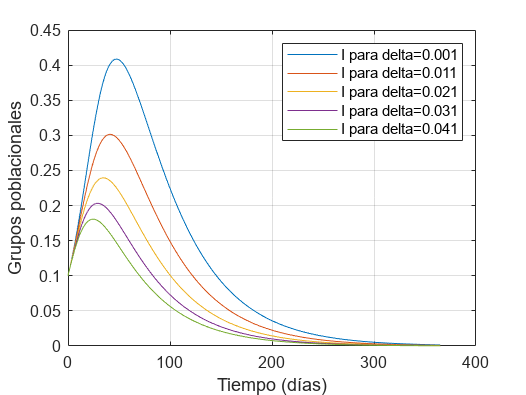

beta=0.1; %Tasa de transmisión
delta=0.001; %Tasa de vacunación
gamma=0.02; %Tasa de recuperación
contador=1; %contador para ciclo de solución
syms s(t) i(t) r(t) v(t)

FS=-beta*s*i-delta*s; %EC susceptibles a infección
FI=beta*s*i-gamma*i; %EC infectados
FR=gamma*i; %EC recuperados
FV=delta*s; %EC vacunados
fn=odeFunction([FS FI FR FV],[s i r v]);

ci=[0.8 0.1 0 0.1]; %Condición inicial [%susceptibles, %infectados, %recuperados, %vacunados]

h = 1.0; %paso o salto en rango de tiempo
tmin = 0; %tiempo inicial
tmax = 365; %tiempo final
tspan = tmin:h:tmax;

[tiempo,salida]=ode45(fn,tspan,ci);

figure
plot(tiempo,salida(:,2))
grid on
xlabel("Tiempo (días)")
ylabel("Grupos poblacionales")
hold on
delta=delta+0.01;

while contador<5 %Ciclo while para crear gráfica
    contador=contador+1; %Aumento de contador
    
%Planteamiento de ecuaciones con nuevo gamma
    FS=-beta*s*i-delta*s; %EC susceptibles a infección
    FI=beta*s*i-gamma*i; %EC infectados
    FR=gamma*i; %EC recuperados
    FV=delta*s; %EC vacunados
    fn=odeFunction([FS FI FR FV],[s i r v]);

    [tiempo,salida]=ode45(fn,tspan,ci);

    plot(tiempo,salida(:,2))
    grid on
    xlabel("Tiempo (días)")
    ylabel("Grupos poblacionales")
    hold on
    delta=delta+0.01; %Aumento de delta
end
legend("I para delta=0.001","I para delta=0.011","I para delta=0.021","I para delta=0.031","I para delta=0.041")

Como se puede observar en los resultados, al aumentar el valor de la tasa de vacunación se disminuye el valor del pico de tasa de infectados. Asimismo, para lograr una tasa de infectados no mayor al 20% de la población total se requiere una tasa de vacunación mínima de 0.031.

**        Conclusión:**

Del taller realizado anteriormente se observa no solo la funcionalidad de los modelos de ecuaciones diferenciales SIRV sino también su practicidad al momento de realizar análisis de fenomenos tales cómo la esparción de enfermedades, haciéndo que estos modelos no solo permitan analizar el comportamiento de enfermedades en función de sus características y las del entorno, sino que también permitan realizar una predicción de su esparcimiento a futuro según las variables que lo definen.

Lo anterior hace que estos modelos permitan realizar predicciones y modelos de planificación aplicables a la realidad con el fin de gestionar futuras endemias y enfermedaddes potencialmente contagiosas.